# Soft Actor Critic Reinforcement Learning Mobile Robot Navigation

This example uses Soft Actor Critic(SAC) based reinforcement learning to develop the mobile robot navigation. For a brief summary of the SAC algorithm, see [Soft Actor Critic(SAC) Agents](https://www.mathworks.com/help/reinforcement-learning/ug/sac-agents.html).

This example scenario trains a mobile robot to navigate from location A to location B to avoid obstacles given range sensor readings that detect obstacles in the map. The objective of the reinforcement learning algorithm is to learn what controls (linear and angular velocity) for navigation from an initial to goal position and  during the travel also can avoid colliding into obstacles.  This example uses an occupancy map of a known environment to generate range sensor readings, detect obstacles, and check collisions the robot may make. The range sensor readings are the observations for the SAC agent, and the linear and angular velocity controls are the action.

### Load Map

Load a map matrix, `simpleMap or complexMap`, that represents the environment for the robot.

load simpleMap.mat
load complexMap.mat
map1= 1;
if map1==1
    mapMatrix=simpleMap;
else
    mapMatrix=complexMap;
end
mapScale = 1;

### Range Sensor Parameters

Next, set up a `rangeSensor` object which simulates a noisy range sensor. The range sensor readings are considered observations by the agent. Define the angular positions of the range readings, the max range, and the noise parameters.

scanAngles = [0 : 2*pi/35 :2*pi];% 36 lidar ray in 360 degree
maxRange = 4;
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

### Robot Parameters

The action of the agent is a two-dimensional vector $a = [v , \omega] $ where $v$ and $\omega$ are the linear and angular velocities of our robot. The SAC agent uses normalized inputs for both the angular and linear velocities, meaning the actions of the agent are a scalar between -1 and 1, which is multiplied by the `maxLinSpeed` and `maxAngSpeed` parameters to get the actual control. Specify this maximum linear and angular velocity.

Also, specify as per below:

- Maximum speed parameters

- The initial and goal position of the robot as [x y theta]

- Minimum distance before angle correction 

- `isdone` condition for wall detection

- The goal condition and tolerance [x y theta]

% Max speed parameters
maxLinSpeed = 0.3; %0.3
maxAngSpeed = 0.3;

% Initial pose of the robot
initX = 15;  
initY = 15;
initTheta = pi/2;

% Goal pose of the robot.
goalX = 5; 
goalY = 5; 
goalTheta = -pi/2;

% minimum distance before angle correction (final Approach)
min_angle_dis=1;

%isdone condition
minimum_lidar_to_wall=0.25;

%tolarance goal condition
goal_X_max_tolarance = goalX +0.5;
goal_X_min_tolarance = goalX -0.5;
goal_Y_max_tolarance = goalY +0.5;
goal_Y_min_tolarance = goalY -0.5;
goalTheta_max_tolarance = goalTheta +0.874; %5 degree +0.874
goalTheta_min_tolarance = goalTheta -0.874; %5 degree -0.874

maximum  for  x and y  axis at map

maximum_x_y=1000;

SAC observation parameter additional observation other than lidar scan

additional_observation=10;

### Show Map and Robot Positions

To visualize the actions of the robot, create a figure. Start by showing the occupancy map and plot the initial position of the robot.

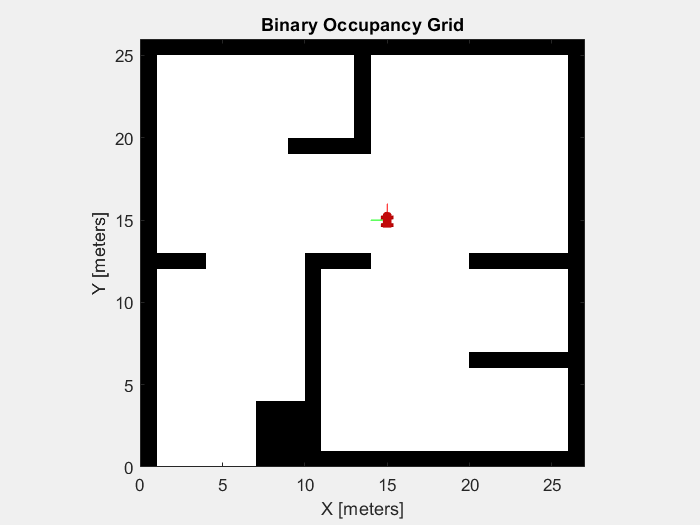

fig = figure("Name","simpleMap");
set(fig, "Visible", "on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX, initY, 0], eul2quat([initTheta, 0, 0]), "MeshFilePath","groundvehicle.stl", "View", "2D");
light;
hold off

### Environment Interface

Create an environment model that takes the action, and gives the observation and reward signals. Specify the provided example model name, AvoidObstaclesMobileRobot, the simulation time parameters, and the agent block name.

mdl = "AvoidObstaclesMobileRobot";
Tfinal = 30;
sampleTime = 0.1;
agentBlk = mdl + "/Agent";

Open the model.

open_system(mdl)

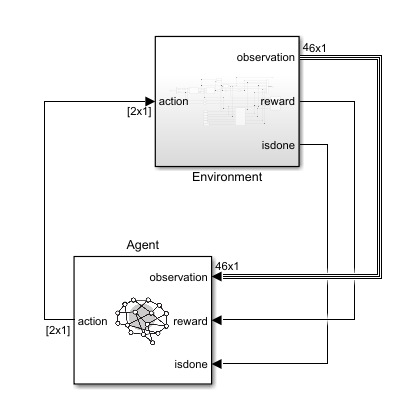

The model contains the `Environment` and `Agent` blocks. The `Agent` block is not defined yet.

Inside the `Environment` Subsystem block, you should see a model for simulating the robot and sensor data. The subsystem takes in the action, generates the observation signal based on the range sensor readings, and calculates the reward based on the distance from obstacles, and the effort of the action commands.

open_system(mdl + "/Environment")

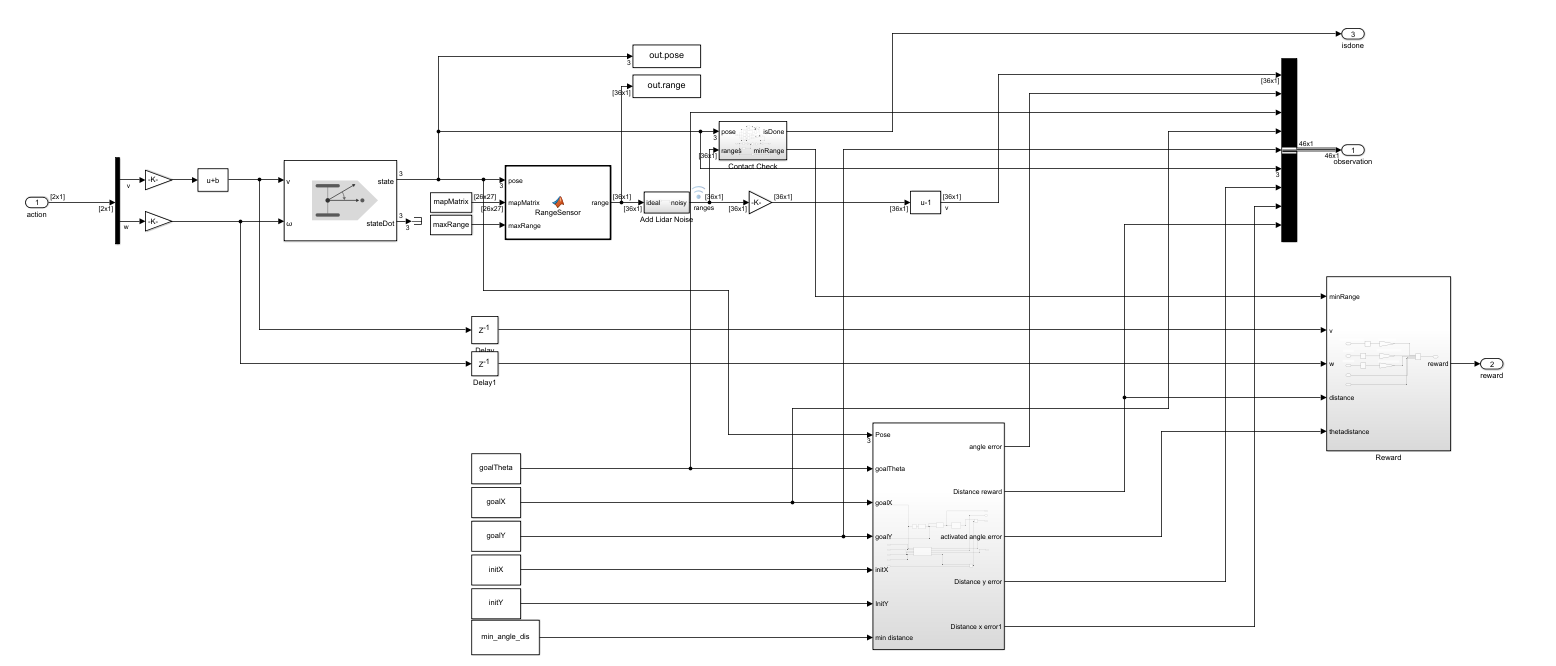

Define observation parameters, `obsInfo`, using the `rlNumericSpec` object and giving the lower and upper limit for the range readings with enough elements for each angular position in the range sensor.

observationwithposeerror=numel(scanAngles)+additional_observation;
obsInfo = rlNumericSpec([observationwithposeerror 1],...
    "LowerLimit",ones(observationwithposeerror,1)*-maximum_x_y,...
    "UpperLimit",ones(observationwithposeerror,1)*maximum_x_y);
numObservations = obsInfo.Dimension(1);

Define action parameters, `actInfo`. The action is the control command vector, $a = [v , \omega] $, normalized to $[-1, 1]$.

numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);

Build the environment interface object using [`rlSimulinkEnv`](https://www.mathworks.com/help/reinforcement-learning/ref/rlsimulinkenv.html). Specify the model, agent block name, observation parameters, and action parameters. Set the reset function for the simulation using `RLAvoidObstaclesResetFcn`. This function restarts the simulation by placing the robot in a new random location to begin avoiding obstacles. 

env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.ResetFcn = @(in)RLAvoidObstaclesResetFcn(in,scanAngles,maxRange,simpleMap);
env.UseFastRestart = "off";

For another example that sets up a Simulink® environment for training, see [Create Simulink Environment and Train Agent](https://www.mathworks.com/help/reinforcement-learning/ug/create-simulink-environment-and-train-agent.html).

## SAC Agent

A SAC agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](https://www.mathworks.com/help/reinforcement-learning/ug/create-policy-and-value-function-representations.html).

Create two Q-value critic representations. First, create a first critic deep neural network structure as per below;

%critic 1
statePath1 = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(400,'Name','CriticStateFC1')
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(300,'Name','CriticStateFC2')
    ];
actionPath1 = [
    featureInputLayer(numActions,'Normalization','none','Name','action')
    fullyConnectedLayer(300,'Name','CriticActionFC1')
    ];
commonPath1 = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1,'Name','CriticOutput')
    ];

criticNet1 = layerGraph(statePath1);
criticNet1 = addLayers(criticNet1,actionPath1);
criticNet1 = addLayers(criticNet1,commonPath1);
criticNet1 = connectLayers(criticNet1,'CriticStateFC2','add/in1');
criticNet1 = connectLayers(criticNet1,'CriticActionFC1','add/in2');

View the critic network configuration.

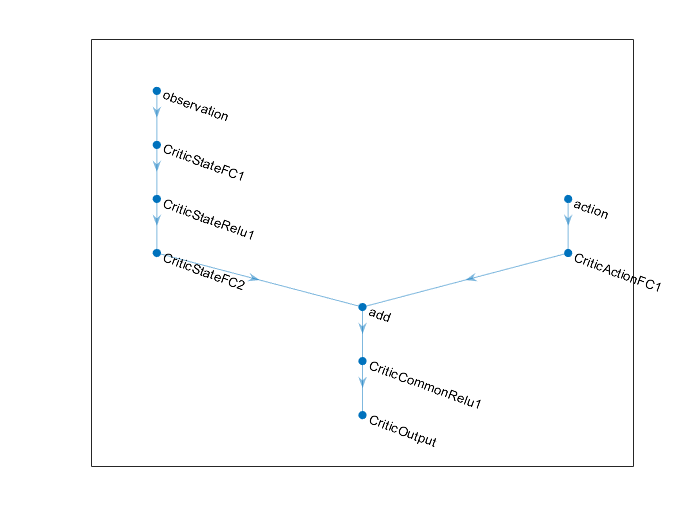

figure
plot(criticNet1)

Create second critic network.

%critic 2
statePath2 = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(400,'Name','CriticStateFC1')
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(300,'Name','CriticStateFC2')
    ];
actionPath2 = [
    featureInputLayer(numActions,'Normalization','none','Name','action')
    fullyConnectedLayer(300,'Name','CriticActionFC1')
    ];
commonPath2 = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1,'Name','CriticOutput')
    ];

criticNet2 = layerGraph(statePath2);
criticNet2 = addLayers(criticNet2,actionPath2);
criticNet2 = addLayers(criticNet2,commonPath2);
criticNet2 = connectLayers(criticNet2,'CriticStateFC2','add/in1');
criticNet2 = connectLayers(criticNet2,'CriticActionFC1','add/in2');

View the  second critic network configuration.

figure
plot(criticNet2)

Next, specify options for the critic representation using [`rlRepresentationOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rlrepresentationoptions.html).

% create  critic using rlRepresentation
criticOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-3,... 
                                        'GradientThreshold',1,'L2RegularizationFactor',2e-4);

Finally, Create the critic representations. Use two different network structure for both critics. The SAC agent initializes the two networks using different default parameters.You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [`rlQValueRepresentation`](https://www.mathworks.com/help/reinforcement-learning/ref/rlqvaluerepresentation.html).

critic1 = rlQValueRepresentation(criticNet1,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);
critic2 = rlQValueRepresentation(criticNet2,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);

The SAC agent decides which action to take given observations using an actor representation. Create an actor deep neural network. 

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(400, 'Name','commonFC1')
    reluLayer('Name','CommonRelu')];
meanPath = [
    fullyConnectedLayer(300,'Name','MeanFC1')
    reluLayer('Name','MeanRelu')
    fullyConnectedLayer(numActions,'Name','Mean')
    ];
stdPath = [
    fullyConnectedLayer(300,'Name','StdFC1')
    reluLayer('Name','StdRelu')
    fullyConnectedLayer(numActions,'Name','StdFC2')
    softplusLayer('Name','StandardDeviation')
    ];

concatPath = [
    concatenationLayer(1,2,'Name','GaussianParameters')
    ];

actorNetwork = layerGraph(statePath);
actorNetwork = addLayers(actorNetwork,meanPath);
actorNetwork = addLayers(actorNetwork,stdPath);
actorNetwork = addLayers(actorNetwork,concatPath);
actorNetwork = connectLayers(actorNetwork,'CommonRelu','MeanFC1/in');
actorNetwork = connectLayers(actorNetwork,'CommonRelu','StdFC1/in');
actorNetwork = connectLayers(actorNetwork,'Mean','GaussianParameters/in1');
actorNetwork = connectLayers(actorNetwork,'StandardDeviation','GaussianParameters/in2');

View the actor network configuration.

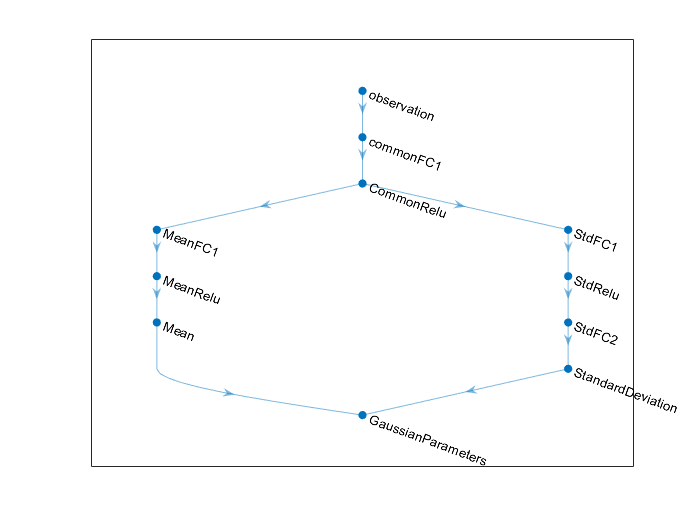

figure
plot(actorNetwork)

Specify actorOptions set with rlRepresentationOptions for reinforcement learning agent representations for actor. For more information, see  [rlRepresentationOptions](https://www.mathworks.com/help/reinforcement-learning/ref/rlrepresentationoptions.html).

actorOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-3,...
                                       'GradientThreshold',1,'L2RegularizationFactor',1e-5);

Create the actor with [rlStochasticActorRepresentation](https://www.mathworks.com/help/reinforcement-learning/ref/rlstochasticactorrepresentation.html), using the deep neural network, the observations and action specification objects, as well as the names of the network input layer.

actor = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,actorOptions,...
    'Observation',{'observation'});

### Create SAC agent object

Specify the agent options. For more information, see  [rlSACAgentOptions](https://www.mathworks.com/help/reinforcement-learning/ref/rlsacagentoptions.html).

SampleTime = 0.1;
agentOptions = rlSACAgentOptions;
agentOptions.SampleTime = SampleTime;
agentOptions.PolicyUpdateFrequency = 5;
agentOptions.CriticUpdateFrequency = 5;
agentOptions.DiscountFactor = 0.99;
agentOptions.TargetSmoothFactor = 1e-3;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.MiniBatchSize = 128;
agentOptions.NumStepsToLookAhead = 3;
agentOptions.SaveExperienceBufferWithAgent =true;
agentOptions.ResetExperienceBufferBeforeTraining = true;

Then create the SAC agent  with rlSACAgent using the specified actor representation, critic representation, and agent options. The `obstacleAvoidanceAgent` variable is used in the model for the `Agent` block.For more information, see [rlSACAgent](https://www.mathworks.com/help/reinforcement-learning/ref/rlsacagent.html) .

obstacleAvoidanceAgent = rlSACAgent(actor,[critic1 critic2],agentOptions);
open_system(mdl + "/Agent")

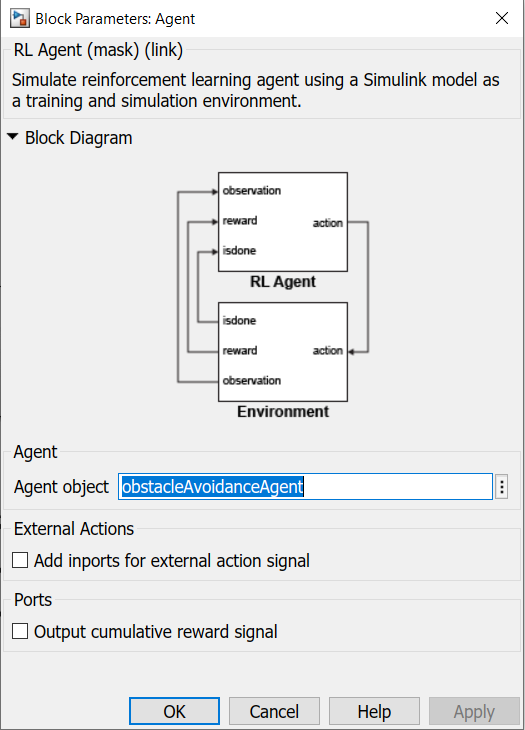

## Reward

The reward function for the agent is modeled as shown.

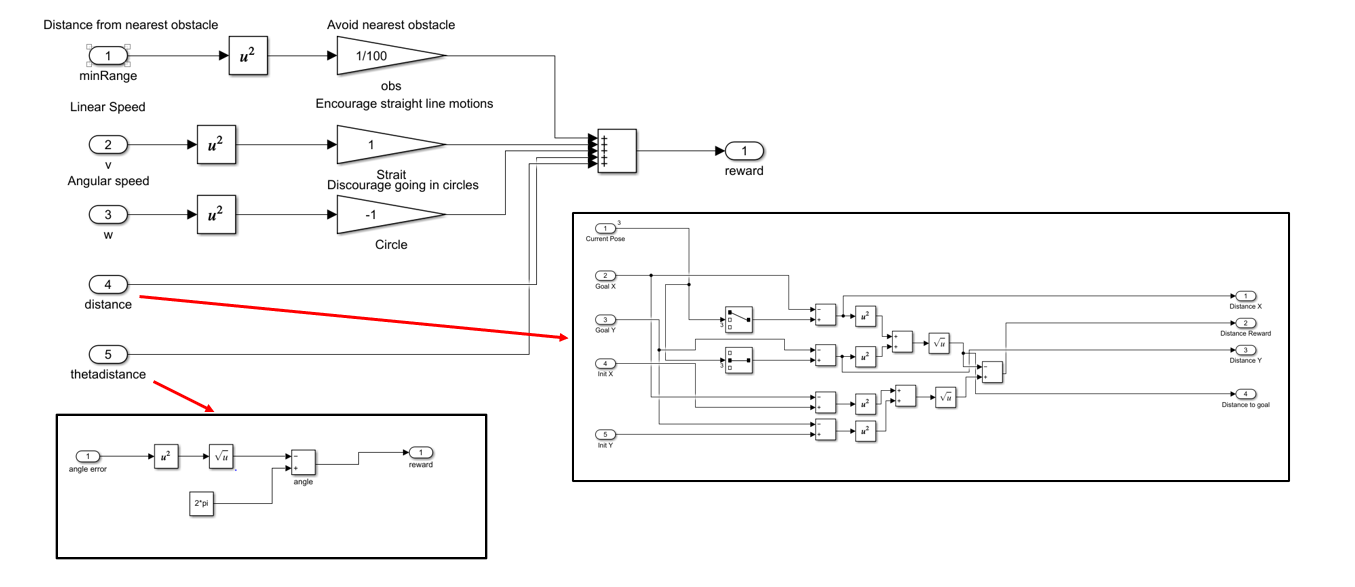

The agent is rewarded to avoid the nearest obstacle, which minimizes the worst-case scenario. Additionally, the agent is given a positive reward for higher linear speeds, and is given a negative reward for higher angular speeds. This rewarding strategy discourages the agent's behavior of going in circles. In the navigation phase, the agent will be given distance reward based on positioning robot, nearer to goal position is more high reward. While the theta distance reward is given based on robot angle heading at the goal position.

Tuning your rewards is key to properly training an agent, so your rewards vary depending on your application.

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Train for at most 26000 episodes, with each episode lasting at most `ceil(Tf/Ts)` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and enable the command line display (set the `Verbose` option to true).

- Save a copy of the agent for each episode where the cumulative reward is greater than 10000.

- Save a copy of the agent for each episode where if  the episode reward is greater than 1000.

For more information, see [`rlTrainingOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rltrainingoptions.html).

maxEpisodes = 2000;
maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",10000, ...
    "Verbose", true, ...
    "Plots","training-progress");
trainOpts.SaveAgentCriteria = "EpisodeReward";
trainOpts.SaveAgentValue = 1000;

Train the agent using the [`train`](https://www.mathworks.com/help/reinforcement-learning/ug/train-reinforcement-learning-agents.html) function. Training is a computationally-intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false; % Toggle this to true for training. 

if doTraining
    % Load the agent from the previous session
    trainingStats = train(obstacleAvoidanceAgent,env,trainOpts);
%     save ('origin_26000.mat','obstacleAvoidanceAgent') %% activate if want to save or copy the agent at the end training
    
else
    % Load pretrained agent for the example. 
    rng(0);
    load agent_trained.mat obstacleAvoidanceAgent 
end

The **Reinforcement Learning Episode Manager** can be used to track episode-wise training progress. As the episode number increases, you want to see an increase in the reward value.

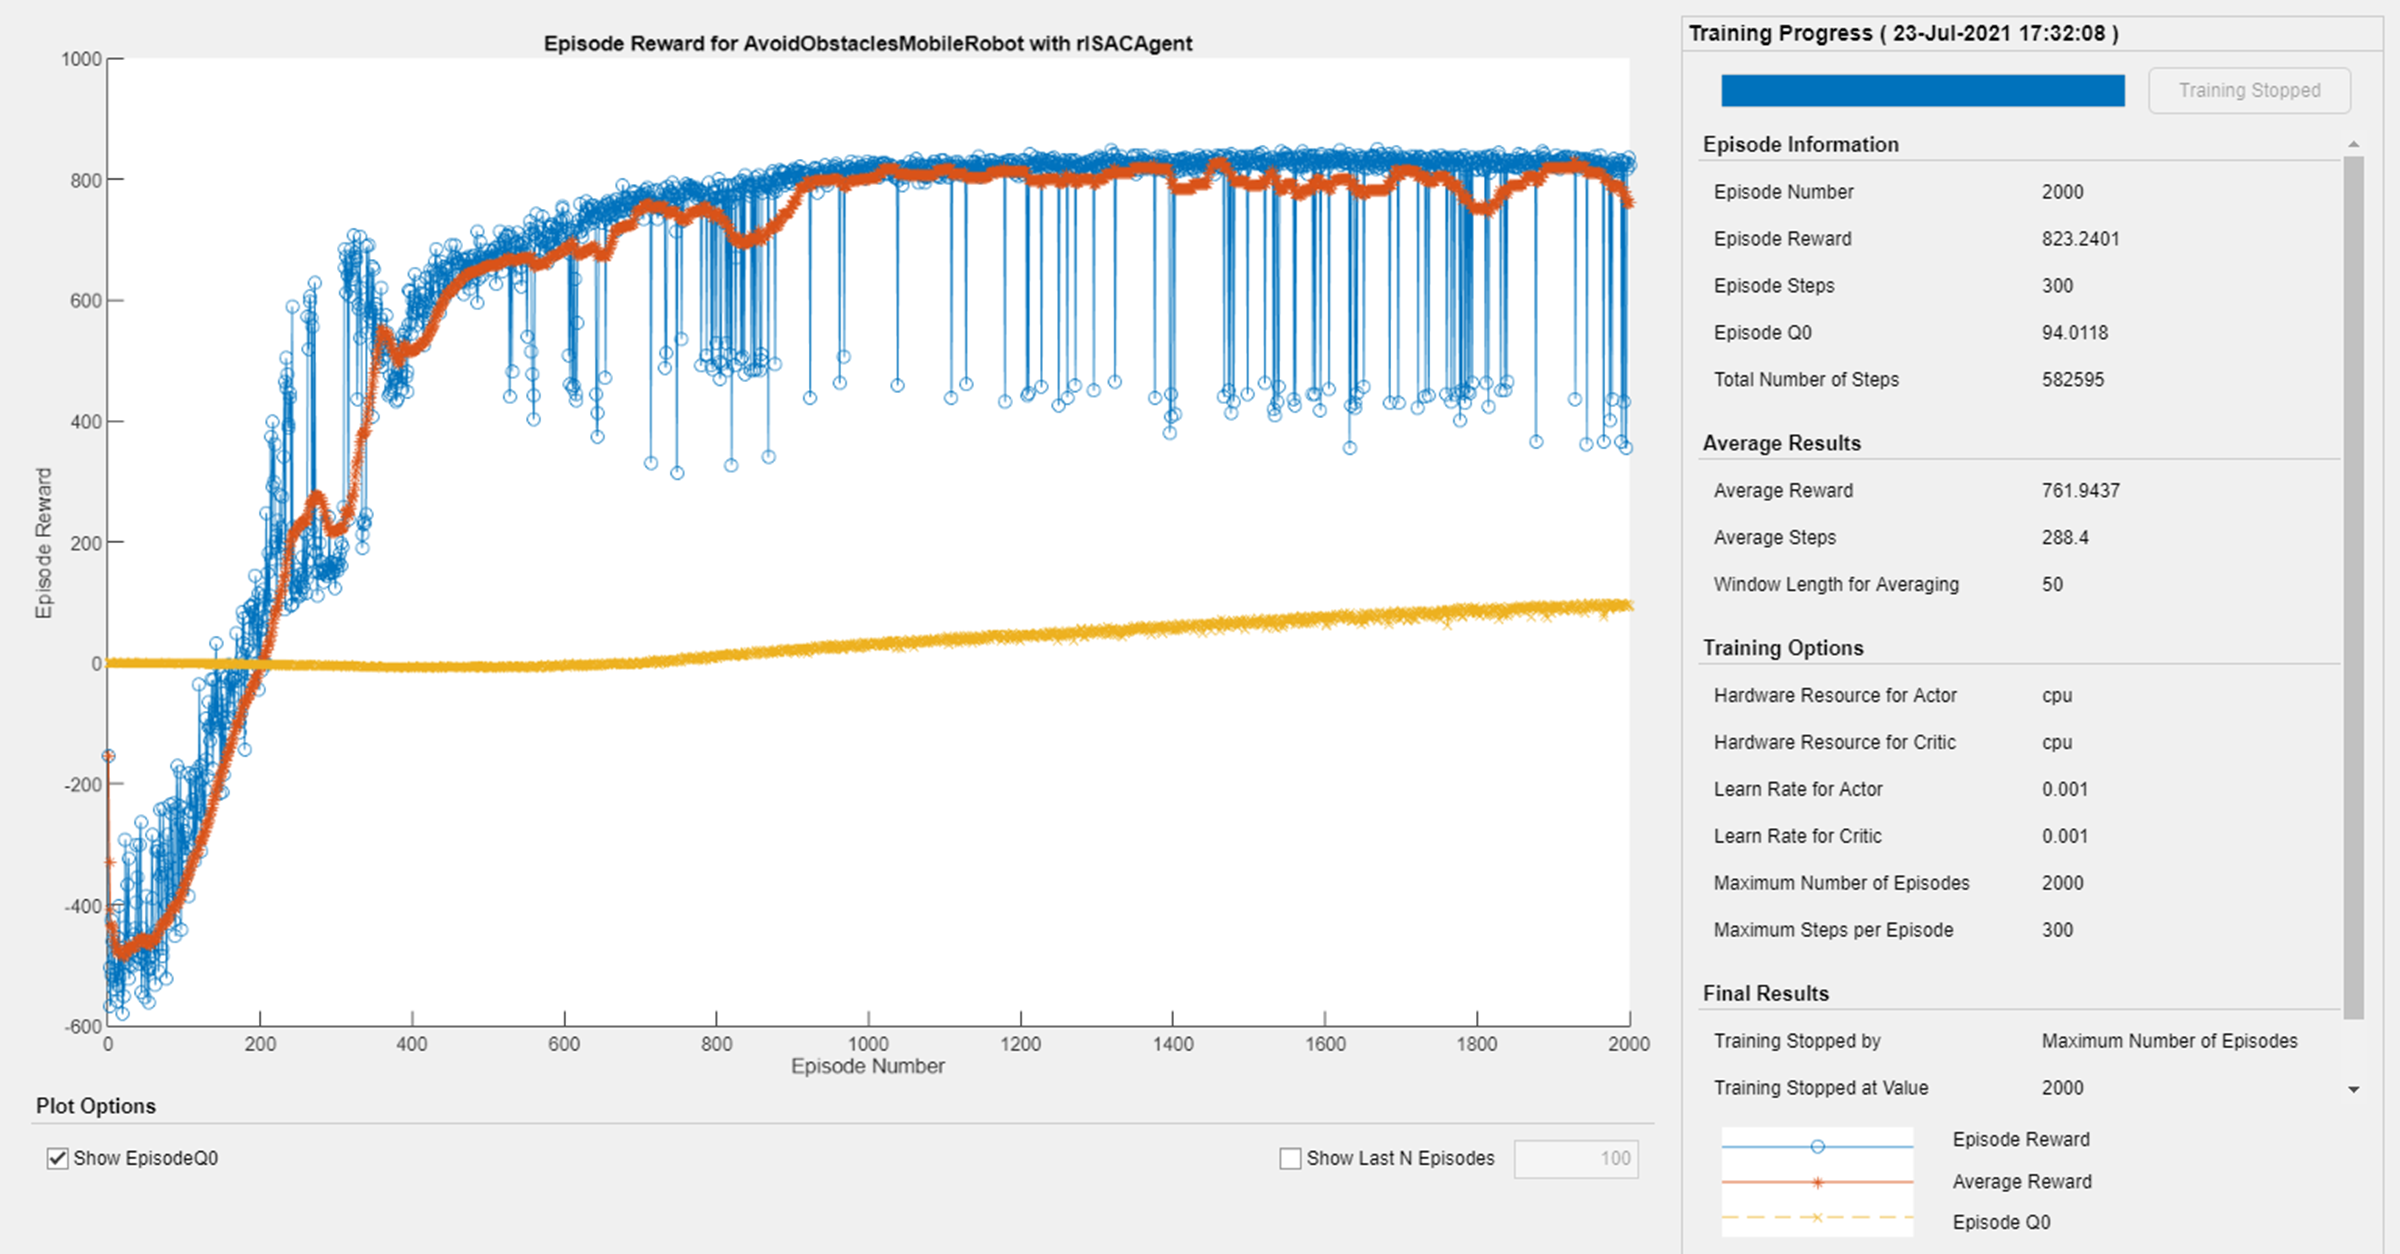

## Simulate

Fix the random generator seed for reproducibility.

rng(0);

Use the trained agent to simulate the robot driving in the map for navigation  from an inital  to goal position and  avoiding obstacles.

out = sim("AvoidObstaclesMobileRobot.slx");

## Visualize

To visualize the simulation of the robot driving around the environment with range sensor readings, use the helper, `AvoidObstaclesPosePlot`.

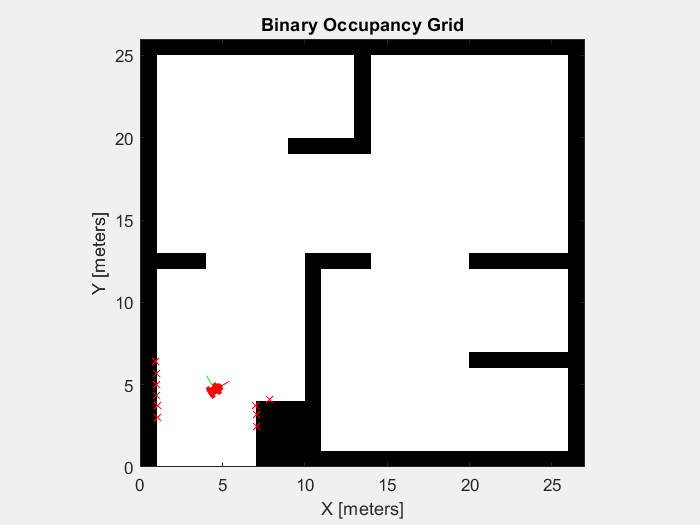

for i = 1:10:size(out.range, 3)
    u = out.pose(i, :);
    r = out.range(:, :, i);
    AvoidObstaclesPosePlot(u, mapMatrix, mapScale, r, scanAngles, ax);
end